% copyright to North Carolina State Univiersity, Ning Lu

% Date: August 2, 2022 

% ECE 451 Power System Analysis - A Matlab Tutorial - Reactive Power Compensation

% Shunt Compensation - Calculate capacitance for a shunt capacitor

clear all
close all

V_rms = 120

V_rms = 120

V_angle = 0 % Using voltage as a reference

V_angle = 0

f = 60

f = 60


I_rms = 100

I_rms = 100

I_angle = -30 % Note that this is in degree. current behind voltage: inductive load

I_angle = -30

% I_angle = 30 %current ahead of voltage, capacitive
% I_angle = 0 % current in phase with voltage, resistive

%phasor representation of voltage
V = V_rms *(cos(deg2rad(V_angle)) + 1j*sin(deg2rad(V_angle)));
I = I_rms *(cos(deg2rad(I_angle)) + 1j*sin(deg2rad(I_angle)));
PF = cosd(V_angle-I_angle)

PF = 0.8660


fprintf('Voltage in the Rectangular Form: %f%+fj\n', real(V), imag(V))

Voltage in the Rectangular Form: 120.000000+0.000000j


fprintf('Current in the Rectangular Form: %f%+fj\n', real(I), imag(I))

Current in the Rectangular Form: 86.602540-50.000000j


fprintf('Power factor is cos(V_angle-I_angle): %f\n', PF)

Power factor is cos(V_angle-I_angle): 0.866025


% V = V_rms *(cosd(V_angle) + 1j*sind(V_angle))

% An alternative way for converting a vector with given magnitude and angle to a complex number
V = V_rms * exp (degtorad(V_angle)*1i)

V = 120

I = I_rms * exp (degtorad(I_angle)*1i)

I = 86.6025 - 50.0000i

Compute the complex power, real and reactive power consumed by the load

S = V*conj(I) % complex power consumed by the load

S = 1.0392e+04 + 6.0000e+03i

P = real(S) % real power consumed by the load

P = 1.0392e+04

Q = imag(S) % reactive power consumed by the load

Q = 6.0000e+03

Z = V/I % the load impedance 

Z = 1.0392 + 0.6000i

w = 2*pi*f % the angular frequency

w = 376.9911

Compute if we want to connect a capacitor in parrallel with the load to correct the power factor to a certain value, what the capacitance of the capacitor should be?

PF_targetvalues = [PF:0.01:1.0 1.0];
no_points = length(PF_targetvalues);
Q_cap = zeros(1, no_points);
Cap_parallel = zeros(1, no_points);
I_cap = zeros(1, no_points);
Q_cap_cal = zeros(1, no_points);

for i = 1:no_points
    
    PF_corrected = PF_targetvalues(i); % This is our targeted power factor when adding the parallel capacitor to the circuit
    
    Q_corrected = P/PF_corrected*sqrt(1-PF_corrected^2); % the reactive power after the power factor correction
    
    Q_cap(i) = Q - Q_corrected; % This is the reactive power required from the capacitor
    
    Cap_parallel(i) = Q_cap(i)/abs(V)^2/w;  % Note that as the cap is in parallel with the load, Vcap = V.
    
    % We can validate our results by computing the capacitor branch current 
    Z_cap = 1/(1j*w*Cap_parallel(i)); % capacitor impedance
    I_cap(i) = V/Z_cap; % capacitor branch current
    Q_cap_cal(i) = conj(I_cap(i))*V; % Because the capacitor provides reactive power to the circuit, its reactive power is negative. 
end


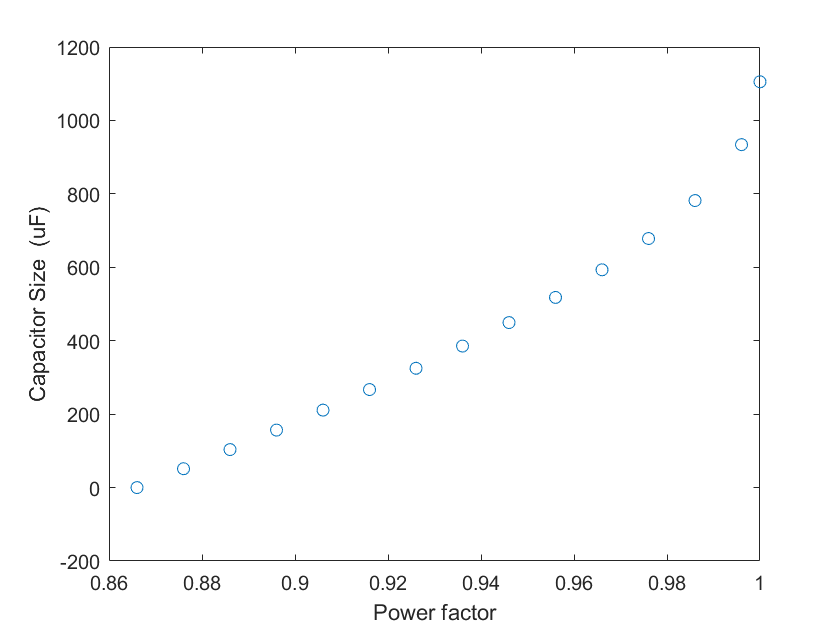


figure(1)
plot(PF_targetvalues, Cap_parallel*10^6, 'o')
xlabel('Power factor');ylabel('Capacitor Size  (uF)')

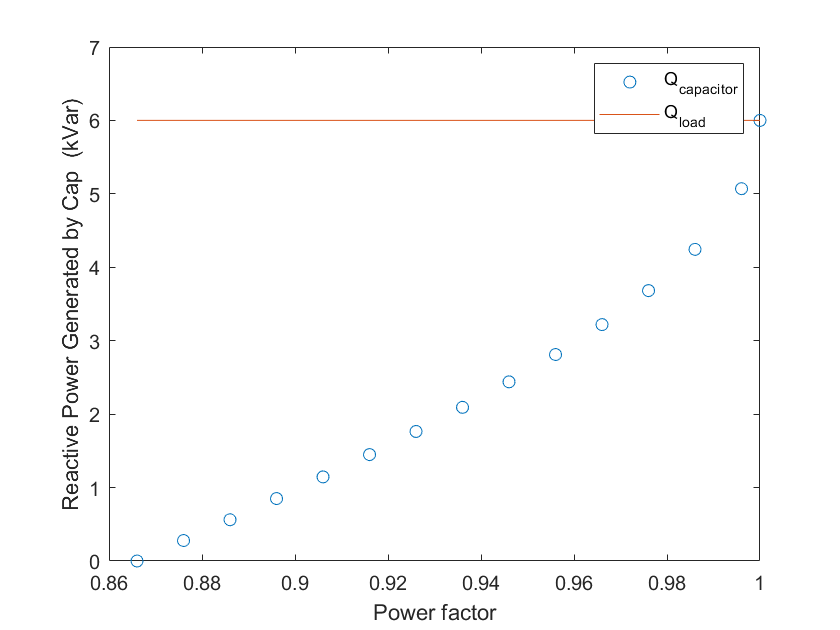


figure(2)
plot(PF_targetvalues, Q_cap/1000,'o') %using kVar instead of Var
hold on
plot(PF_targetvalues, Q*ones(1, no_points)/1000)  %using kVar instead of Var
ylim([0 Q/1000+1])
xlabel('Power factor');ylabel('Reactive Power Generated by Cap  (kVar)')
legend('Q_{capacitor}','Q_{load}')
hold off

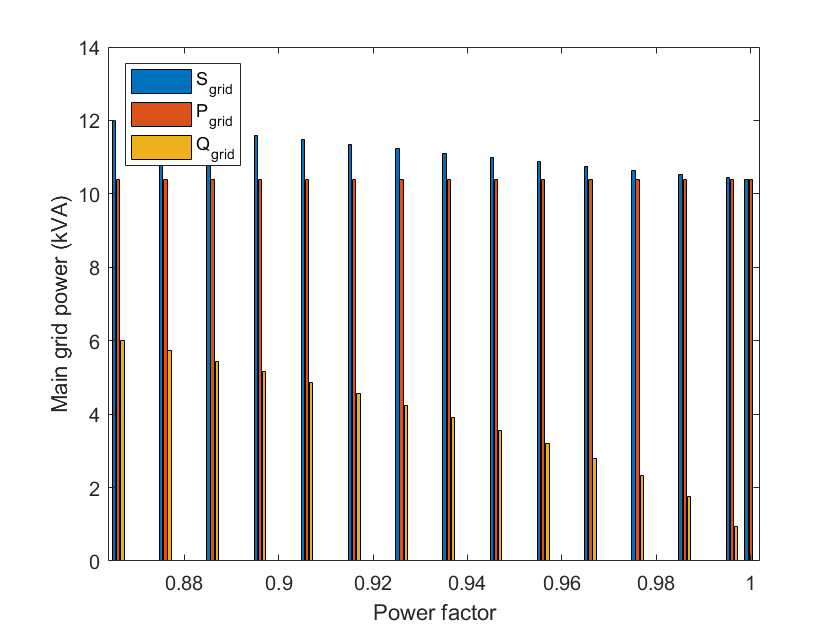


figure(3)
S_maingrid = P./PF_targetvalues;
Results = [S_maingrid; P*ones(1,no_points); Q*ones(1,no_points)-Q_cap]/1000;

bar(PF_targetvalues, Results) %using kVA instead of VA
xlabel('Power factor');ylabel('Main grid power (kVA)')
legend({'S_{grid}','P_{grid}','Q_{grid}'},'Location','northwest')

Compute for the voltage drop at the load bus.  Note that by providing the reactive power localy, the transformer bus voltage can be lower in order to maintain the load bus voltage at 120 V

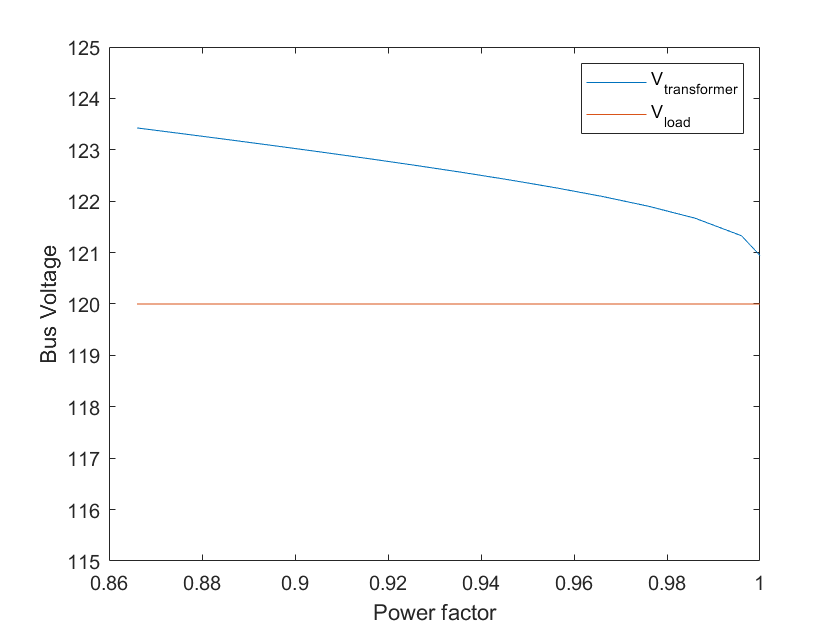

Z_line = 0.01 +1j*0.05;
delta_V = Z_line * (I + I_cap);

figure(4)
plot(PF_targetvalues, abs(V+delta_V))
hold on
plot(PF_targetvalues, V*ones(1, no_points))
xlabel('Power factor');ylabel('Bus Voltage')
ylim([115 125])
legend('V_{transformer}','V_{load}')
hold off